# Telescope sensitivity analysis due to M1 AHU vibration forces

Preamble

- Clear workspace

- Radians to mas ($10^{-3}$ arc seconds) conversion constant

clearvars

% Radians to mili arc second conversion constant
rad2mas = (180/pi * 3600 * 1000);
% Root of the sum of squared values function
rss = @(x,dir)sqrt(sum(x.^2,dir));

## Load PSD of ATA vibration data


if(1)
    ata_psd_folder = '/Users/rromano/Workspace/fromDaveS/Vibration/Analysis';
    data = readmatrix(fullfile(ata_psd_folder,'Papst1_10.csv'));
    freq = data(6:500,1);
    FM = data(6:500,2:7);
else
    ata_psd_folder = '/Users/rromano/Workspace/vibrations';  
    load(fullfile(ata_psd_folder,'fan_transferfunctions_and_psd.mat'),'f_P','P_fan1');
    assert(sum(f_P(:,1)-f_P(:,3)) == 0,'Inconsistent frequency vector!')
    freq = f_P(:,1);
end

## Load NS or LTAO RTFs

The variable `rtf` is a $21\times21$matrix transfer function. The NS or LTAO (depending on the argument state of `NS_MODE`) tip-tilt rejection transfer function (RTF) fills the first 14 main diagonal entries. The differential piston RTF fills the last 7 diagonal elements if the checkbox is unchecked, meaning that one assumes the LTAO observing mode. Otherwise, those diagonals are filled with 1s. The rejection transfer function matrix aims at reproducing the effect of the wavefront control loops.

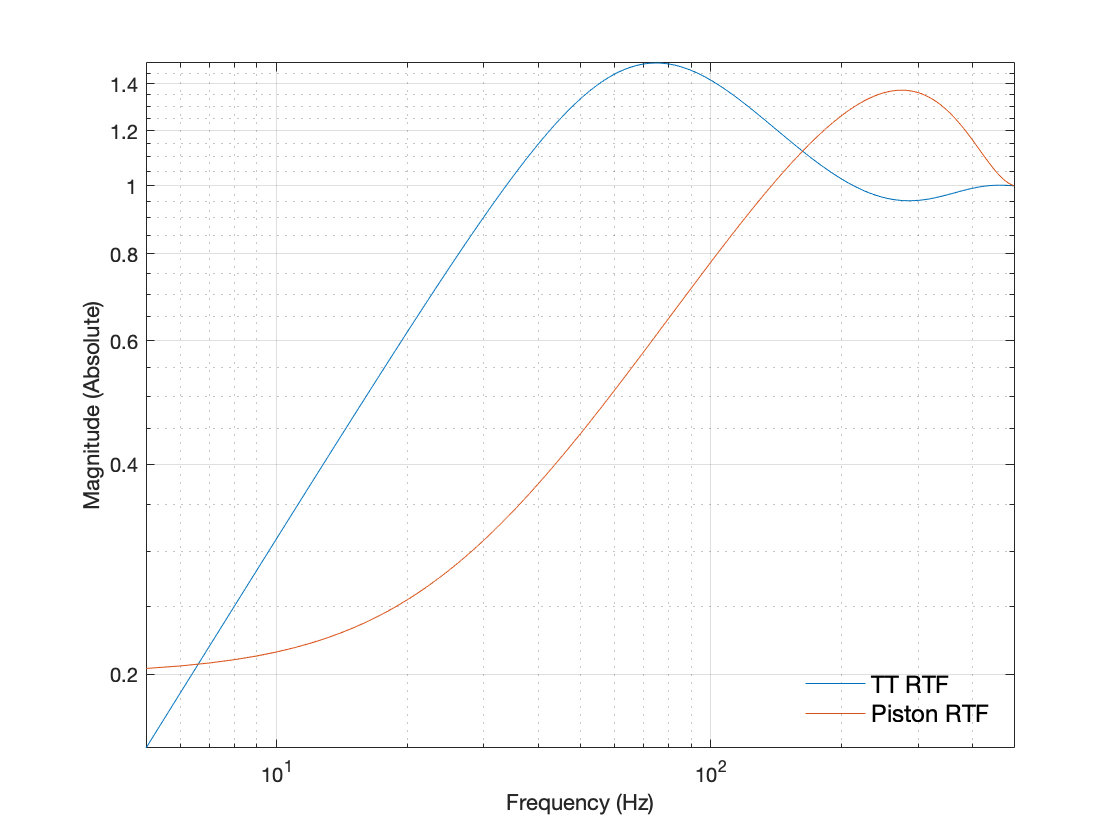

om = 2*pi*freq;
if(~true)
    rtf(1:14,1:14) = eye(14)*frd(oad_NS_rtf(om),om);  
    rtf(15:21,15:21) = eye(7)*frd(tf(1,1),om);
else    
    rtf(1:14,1:14) = eye(14)*frd(oad_AOTT_rtf(om),om);
    rtf(15:21,15:21) = eye(7)*frd(getRTF_DP(om),om);
end

if(true)
    figure;
    loglog(om/2/pi,abs(squeeze(rtf.ResponseData(1,1,:)))); hold on;
    loglog(om/2/pi,abs(squeeze(rtf.ResponseData(15,15,:))));
    legend('TT RTF','Piston RTF','Fontsize',12,'Location','southeast');
    legend box off;
    xlabel('Frequency (Hz)'); ylabel('Magnitude (Absolute)');
    grid on; hold off; axis tight;
end

## Vibration Analysis Model 

Let $G(\j\omega)$the frequency response matrix represent the GMT structural dynamics whose inputs are the forces and moments applied to nodes at the M1 fan locations and the outputs are the M1 and M2 rigid-body motions. As illustrated in the model diagram below, using a linear approximation (LOM), one gets the segment tip-tilt (TT) and the piston at the exit pupil.

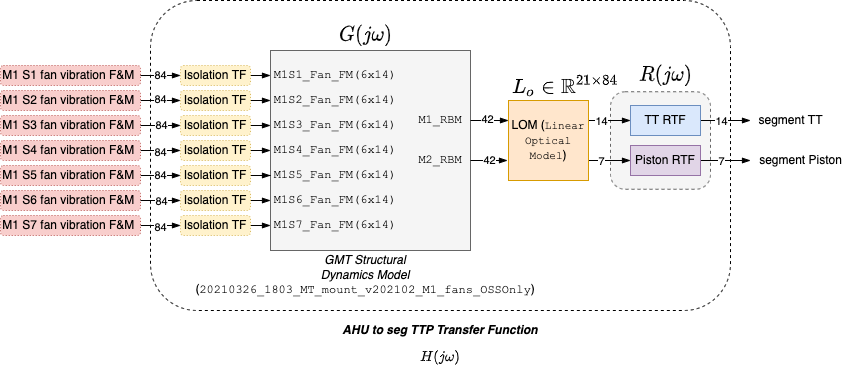

The full telescope model reads as

$H(j\omega) = R(j\omega) L_o G(j\omega) \left(I_{n_u} \otimes H_\text{iso}(j\omega)\right)$, 

where $H_\text{iso}(j\omega)$, $R(j\omega)$ and $L_o$ represent the AHU isolation model, the rejection transfer function frequency response matrix and the linear optical model transformation, respectively. The $n_u$-dimensional matrix is denoted by $I_{n_u}$ ($n_u = 588$) and the symbol $\otimes$ represents the Kronecker product.

### Isolation transfer function

The baseline isolation transfer function (refer to Section 6.3 of GMT-DOC-04861 for the parameters sensitivity study) reads as


$$H_\text{iso}(s) = \frac{\omega_0^2}{\omega_1^2}\frac{s^2 + 2\omega_1s + \omega_1^2}{s^2 + 2 \zeta_\text{iso}\omega_0s + \omega_0^2},$$


where $\omega_0 = 2\pi4.4$rad/s, $\omega_1 = 10\omega_0$, and $\zeta_\text{iso} = 0.05$.

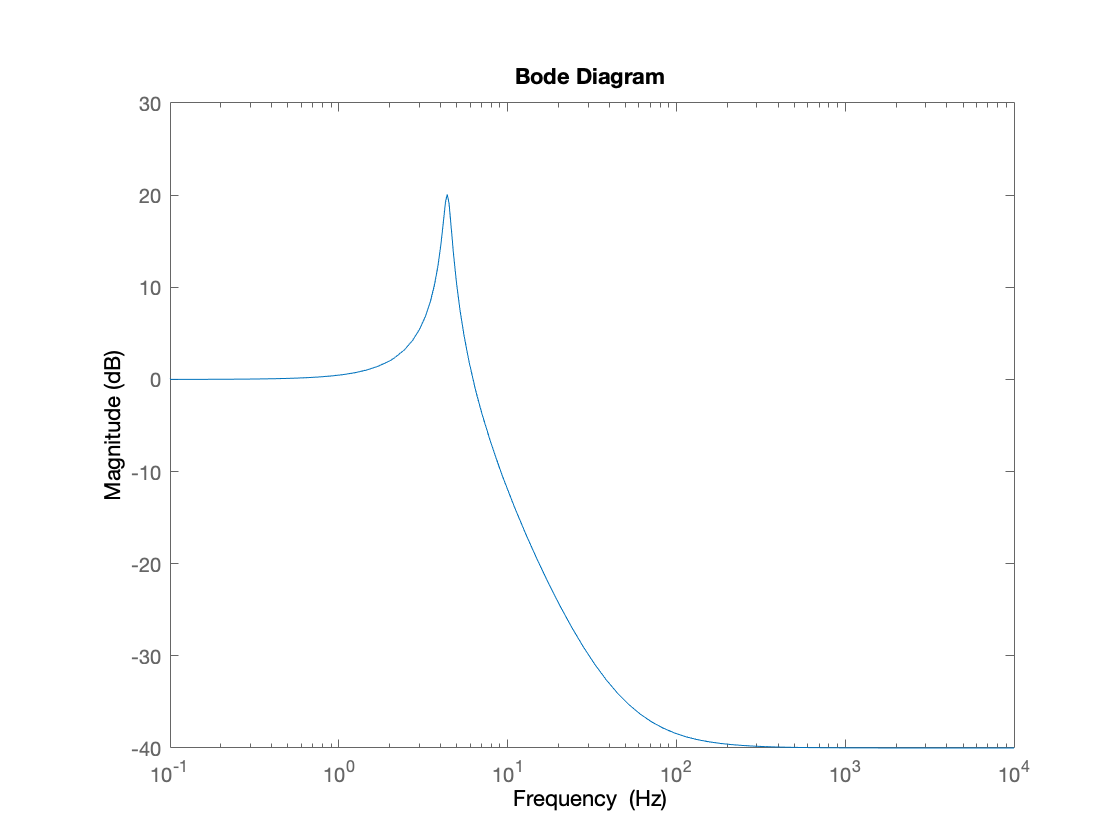

% s = sqrt(-1)*f2(1:end-1)*2*pi;            
om0 = 2*pi*4.4;
om1 = om0*10;
zeta = .05;
Hiso_ = (om0^2)/(om1^2) * tf([1, 2*om1, om1^2],[1, 2*zeta*om0, om0^2]);

if(true)
    figure; %#ok<*UNRCH> 
    hbode_iso = bodeplot(Hiso_);
    setoptions(hbode_iso,'FreqUnits','Hz','PhaseVisible','off');
end

### White noise response

We compute the TT and piston PSD ($$\text{mas}^2/\text{Hz}$$ and $$\text{nm}^2/\text{Hz}$$, respectively) using 


$$Y_\text{TTP}(j\omega) = \left|H(j\omega) \right|^2
\left(\mathbf{1}_{98} \otimes U_{\text{fan}}(j\omega)\right)$$


The symbol $
\otimes$stands for the Kronecker product and $\mathbf{1}_{n_1}$ is an $n_1$-dimensional column vector filled with ones, such that

$\mathbf{1}_3 \otimes U_\text{fan}(j\omega) = \left[
\begin{array}{c}
U_\text{fan}(j\omega) \\ U_\text{fan}(j\omega) \\ U_\text{fan}(j\omega)
\end{array}
\right]$.

The white noise response assumes that a 1$$\text{N}^2/\text{Hz}$$ (or 1$$\left(\text{Nm}\right)^2/\text{Hz}$$) power density is applied to each fan input force (or moment) degree of freedom. The power spectrum density $Y_\text{TTP}$ is 21-dimensional. According to the telescope frequency response model, the first 14 elements of $Y_\text{TTP}$ are the tip-tilt PSD and the last 7 provide the segment piston.

In terms of implementation, the telescope frequency response representing the effect of the load applied on each M1 segment is available from a different data file (`m1s``X``fanTF.mat`) computed beforehand. For this reason, the code below performs two `for` loops: an outer one, which considers the frequency response model due to the excitation on each segment, and an inner iteration, to compute the tip-tilt and piston PSD of each segment.

fprintf("Computing WFE response to white noise vibration...\n");

Computing WFE response to white noise vibration...


for k1 = 1:7
    % Load segment <k1> TF
    load(sprintf("m1s%dfanTF_4ataPSD.mat",k1),"G_fr","ik");
    n_om = length(G_fr.Frequency);
    % Check if PSD and TF frequencies match
    if(~isequal(G_fr.Frequency,om(1:n_om)))
        error("PSD and TF frequencies do not match!")
    end
    % Isolation frequency response
    HisoFR = frd(Hiso_,rtf.Frequency(1:n_om));
    % Apply NS/LTAO RTF
    rtf = frd(rtf.ResponseData(1,1,1:n_om), rtf.Frequency(1:n_om));
    Gtel_rtf_fr = rtf * G_fr;
    H_fr = rtf * G_fr * HisoFR;
    
    % Initialize variables 
    if(~exist("tt_wn_Fxyz","var"))
        tt_wn_Fxyz = zeros(14,7,n_om);
        tt_wn_Mxyz = zeros(14,7,n_om);
        tt_wn_Fxyz_iso = zeros(14,7,n_om);
        tt_wn_Mxyz_iso = zeros(14,7,n_om);
    end
    if(~exist("piston_wn_Fxyz","var"))
        piston_wn_Fxyz = zeros(7,7,n_om);
        piston_wn_Mxyz = zeros(7,7,n_om);
        piston_wn_Fxyz_iso = zeros(7,7,n_om);
        piston_wn_Mxyz_iso = zeros(7,7,n_om);
    end
    
    % PTT computation loop: each iteration provides the Tip/tilt/piston PSD
    % of segment S<k2> as a response of the AHU vibration forces applied on S<k1>. 
    for k2 = 1:7
        % Fxyz input indices (all the 14 fans)
        indFxyz = sort([1:6:14*6,2:6:14*6,3:6:14*6]);
        % Fxyz vibration white noise response
        tt_wn_Fxyz(k2,k1,:) = sum(abs(squeeze(Gtel_rtf_fr.ResponseData(k2,indFxyz,:)))'.^2 ,2);
        tt_wn_Fxyz(k2+7,k1,:) = sum(abs(squeeze(Gtel_rtf_fr.ResponseData(k2+7,indFxyz,:)))'.^2 ,2);
        piston_wn_Fxyz(k2,k1,:) = sum(abs(squeeze(Gtel_rtf_fr.ResponseData(k2+14,indFxyz,:)))'.^2 ,2);
        tt_wn_Fxyz_iso(k2,k1,:) = sum(abs(squeeze(H_fr.ResponseData(k2,indFxyz,:)))'.^2 ,2);
        tt_wn_Fxyz_iso(k2+7,k1,:) = sum(abs(squeeze(H_fr.ResponseData(k2+7,indFxyz,:)))'.^2 ,2);
        piston_wn_Fxyz_iso(k2,k1,:) = sum(abs(squeeze(H_fr.ResponseData(k2+14,indFxyz,:)))'.^2 ,2);
        % Mxyz vibration white noise response
        tt_wn_Mxyz(k2,k1,:) = sum(abs(squeeze(Gtel_rtf_fr.ResponseData(k2,indFxyz+3,:)))'.^2 ,2);
        tt_wn_Mxyz(k2+7,k1,:) = sum(abs(squeeze(Gtel_rtf_fr.ResponseData(k2+7,indFxyz+3,:)))'.^2 ,2);
        piston_wn_Mxyz(k2,k1,:) = sum(abs(squeeze(Gtel_rtf_fr.ResponseData(k2+14,indFxyz+3,:)))'.^2 ,2);
        tt_wn_Mxyz_iso(k2,k1,:) = sum(abs(squeeze(H_fr.ResponseData(k2,indFxyz+3,:)))'.^2 ,2);
        tt_wn_Mxyz_iso(k2+7,k1,:) = sum(abs(squeeze(H_fr.ResponseData(k2+7,indFxyz+3,:)))'.^2 ,2);
        piston_wn_Mxyz_iso(k2,k1,:) = sum(abs(squeeze(H_fr.ResponseData(k2+14,indFxyz+3,:)))'.^2 ,2);
    end
end

DeltaFs = diff(om(1:2)/2/pi);
total_tt_wn_Fxyz = rad2mas*sqrt( DeltaFs*sum(sum(tt_wn_Fxyz)));
total_tt_wn_Fxyz_iso = rad2mas*sqrt( DeltaFs*sum(sum(tt_wn_Fxyz_iso)));
total_piston_wn_Fxyz = 1e9*sqrt( DeltaFs*sum(sum(piston_wn_Fxyz)));
total_piston_wn_Fxyz_iso = 1e9*sqrt( DeltaFs*sum(sum(piston_wn_Fxyz_iso)));
total_tt_wn_Mxyz = rad2mas*sqrt( DeltaFs*sum(sum(tt_wn_Mxyz)));
total_tt_wn_Mxyz_iso = rad2mas*sqrt( DeltaFs*sum(sum(tt_wn_Mxyz_iso)));
total_piston_wn_Mxyz = 1e9*sqrt( DeltaFs*sum(sum(piston_wn_Mxyz)));
total_piston_wn_Mxyz_iso = 1e9*sqrt( DeltaFs*sum(sum(piston_wn_Mxyz_iso)));
fprintf("Done!\n");

Done!


#### Overall tip-tilt and piston effects

Let the $Y_i(j \omega)$ the $i^\text{th}$ element of $Y_\text{TTP}(j\omega)$, we compute the overall TT (in mas) as


$$\phi = 
\sqrt{\int_0^{\infty} \sum_{i=1}^{14} Y_i(j\omega) d\omega }.$$


Similarly, the overall differential piston (in meters) reads as


$$\rho = \sqrt{\int_0^{\infty} \sum_{i=15}^{21} Y_i(j\omega) d\omega }.$$


The overall tip-tilt and piston response to white-noise are as follows.

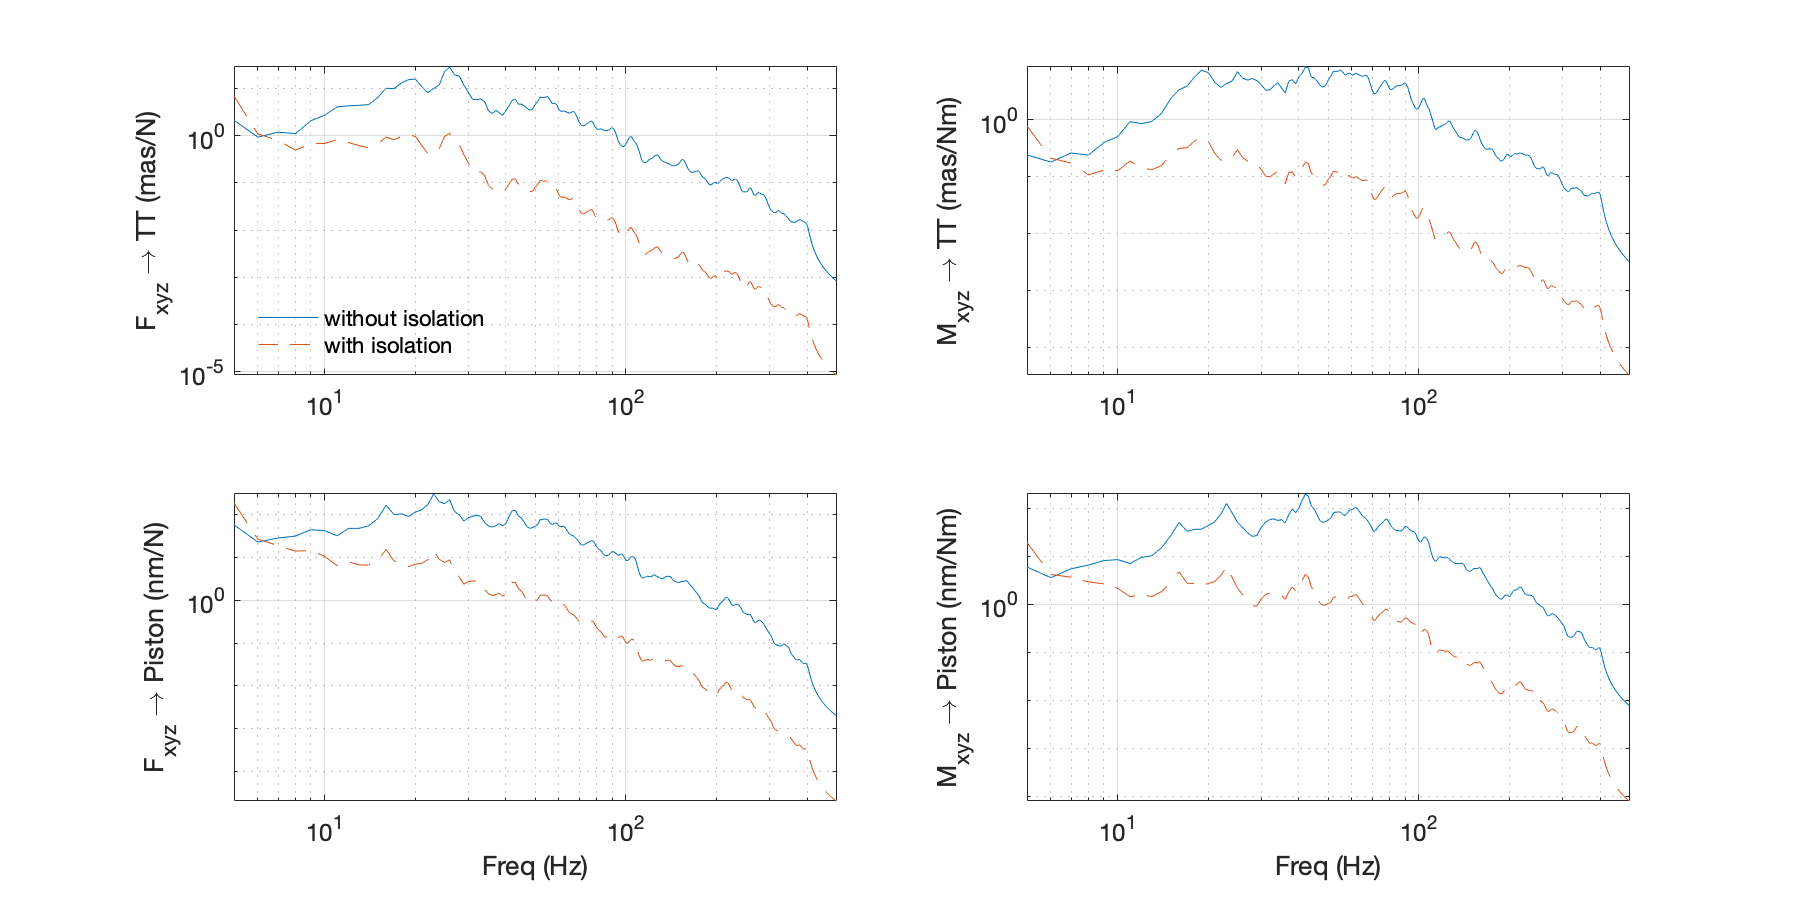

figure;
set(gcf,'Position',[833   323   900   450])
subplot(221);
loglog(freq,total_tt_wn_Fxyz(:),freq,total_tt_wn_Fxyz_iso(:),'--')
set(gca,'Fontsize',12);
ylabel('F_{xyz} \rightarrow TT (mas/N)');
grid on; hold off; axis tight;
legend('without isolation','with isolation',...
    'Location','southwest','NumColumns',1,'Fontsize',11); legend boxoff;
subplot(222)
loglog(freq,total_tt_wn_Mxyz(:),freq,total_tt_wn_Mxyz_iso(:),'--')
set(gca,'Fontsize',12);
ylabel('M_{xyz} \rightarrow TT (mas/Nm)');
grid on; hold off; axis tight;
subplot(223)
loglog(freq,total_piston_wn_Fxyz(:),freq,total_piston_wn_Fxyz_iso(:),'--')
set(gca,'Fontsize',12);
ylabel('F_{xyz} \rightarrow Piston (nm/N)');
grid on; hold off; axis tight;
xlabel('Freq (Hz)');
subplot(224)
loglog(freq,total_piston_wn_Mxyz(:),freq,total_piston_wn_Mxyz_iso(:),'--')
set(gca,'Fontsize',12);
ylabel('M_{xyz} \rightarrow Piston (nm/Nm)');
grid on; hold off; axis tight;
xlabel('Freq (Hz)');

#### Overall wavefront error (WFE) effect

The expression of the overall M1 AHU vibration effect on the wavefront error (WFE) in (in meters) is

$\text{WFE} = \sqrt{\frac{R^2}{4} \left(\frac{1}{3.6\times 10^6}\frac{\pi}{180}\phi\right)^2 + \rho^2}$,

where $R=8.4$m (see Appendix E of GMT-DOC-04861).

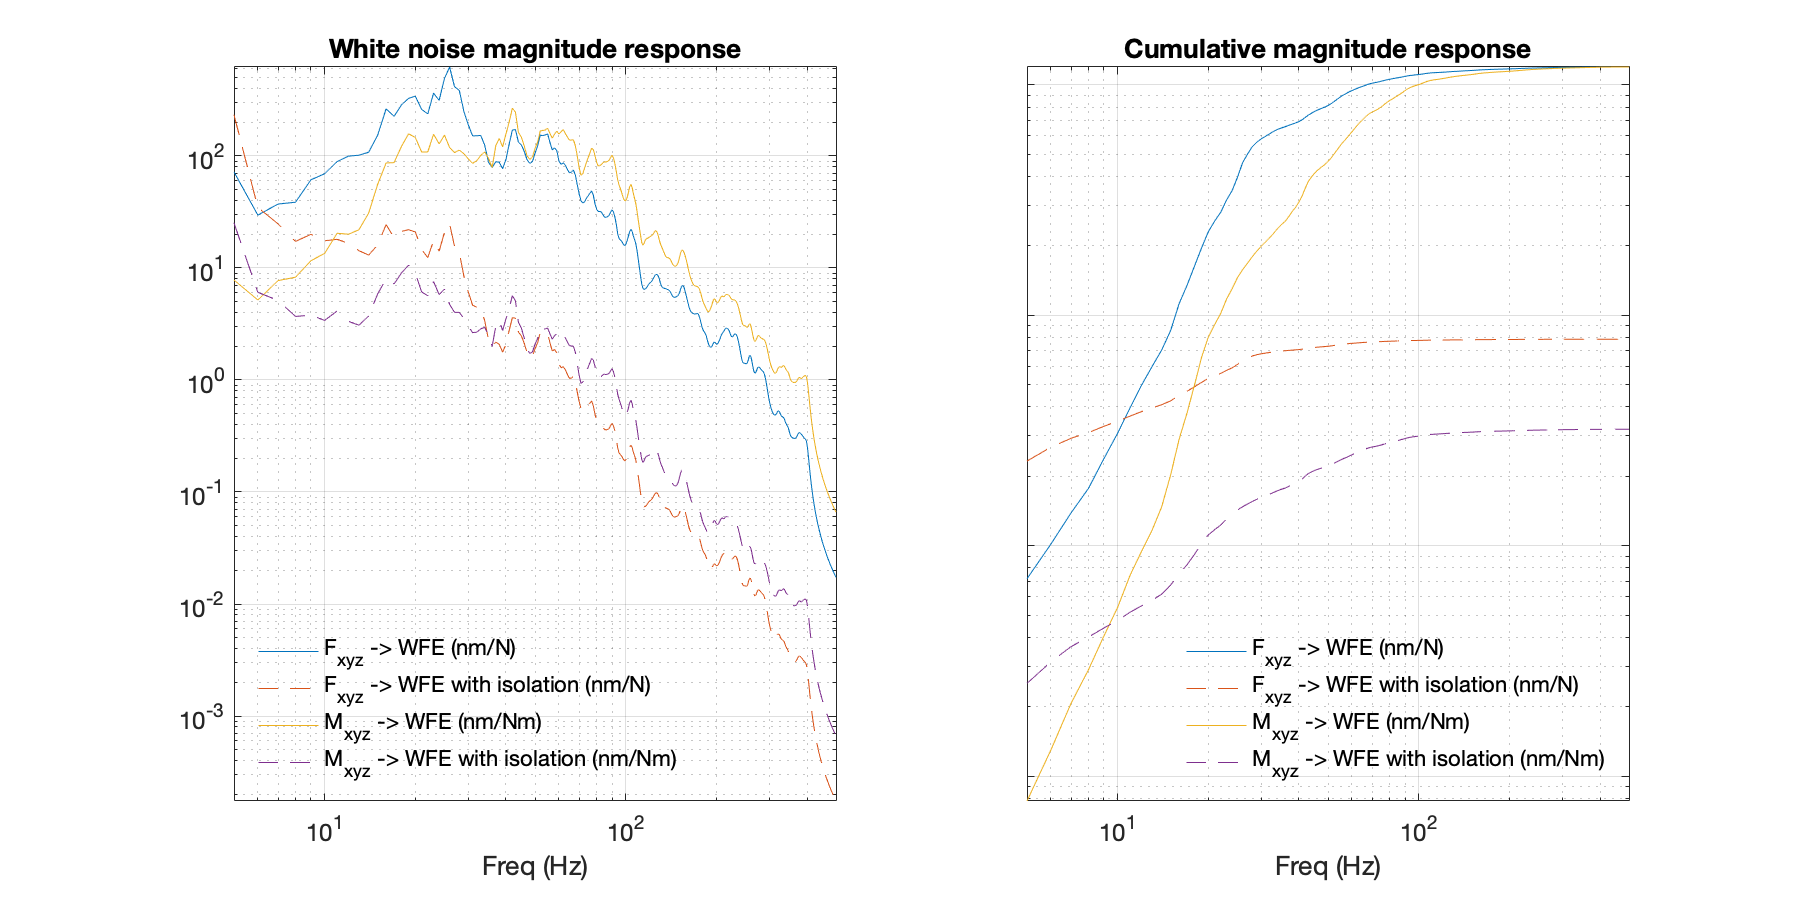

total_tt_wnF = rad2mas*sqrt( DeltaFs*sum(sum(tt_wn_Fxyz)));
total_tt_wnM = rad2mas*sqrt( DeltaFs*sum(sum(tt_wn_Mxyz)));
total_piston_wnF = 1e9*sqrt( DeltaFs*sum(sum(piston_wn_Fxyz)));
total_piston_wnM = 1e9*sqrt( DeltaFs*sum(sum(piston_wn_Mxyz)));
R = 8.4;
total_wfe_wnF = sqrt(((total_tt_wnF/rad2mas).^2 * R^2/4)*1e18 + total_piston_wnF.^2);
total_wfe_wnM = sqrt(((total_tt_wnM/rad2mas).^2 * R^2/4)*1e18 + total_piston_wnM.^2);
total_tt_wnF_iso = rad2mas*sqrt( DeltaFs*sum(sum(tt_wn_Fxyz_iso)));
total_tt_wnM_iso = rad2mas*sqrt( DeltaFs*sum(sum(tt_wn_Mxyz_iso)));
total_piston_wnF_iso = 1e9*sqrt( DeltaFs*sum(sum(piston_wn_Fxyz_iso)));
total_piston_wnM_iso = 1e9*sqrt( DeltaFs*sum(sum(piston_wn_Mxyz_iso)));
total_wfe_wnF_iso = sqrt(((total_tt_wnF_iso/rad2mas).^2 * R^2/4)*1e18 + total_piston_wnF_iso.^2);
total_wfe_wnM_iso = sqrt(((total_tt_wnM_iso/rad2mas).^2 * R^2/4)*1e18 + total_piston_wnM_iso.^2);

figure;
set(gcf,'Position',[833   323   900   450])
subplot(121)
loglog(freq,total_wfe_wnF(:),freq,total_wfe_wnF_iso(:),'--',...
    freq,total_wfe_wnM(:),freq,total_wfe_wnM_iso(:),'--');

% limFreq = 170;
% [~,~,idx]=unique(round(abs(freq-limFreq)),'stable');
% minVal=freq(idx==1);

title("White noise magnitude response")
grid on; hold off; axis tight;
xlabel('Freq (Hz)');
set(gca,'Fontsize',12);
legend('F_{xyz} -> WFE (nm/N)','F_{xyz} -> WFE with isolation (nm/N)',...
    'M_{xyz} -> WFE (nm/Nm)','M_{xyz} -> WFE with isolation (nm/Nm)',...
    'Location','southwest','NumColumns',1,'fontsize',11); legend boxoff;
subplot(122)
loglog(freq,cumsum(total_wfe_wnF(:)),freq,cumsum(total_wfe_wnF_iso(:)),'--',...
    freq,cumsum(total_wfe_wnM(:)),freq,cumsum(total_wfe_wnM_iso(:)),'--');
set(gca,'YTickLabels',[])
grid on; hold off; axis tight;
xlabel('Freq (Hz)');
title("Cumulative magnitude response")
set(gca,'Fontsize',12);
legend('F_{xyz} -> WFE (nm/N)','F_{xyz} -> WFE with isolation (nm/N)',...
    'M_{xyz} -> WFE (nm/Nm)','M_{xyz} -> WFE with isolation (nm/Nm)',...
    'Location','southeast','NumColumns',1,'fontsize',11); legend boxoff;

### Vibration effect analysis based on ATA's data

Here we compute $Y_\text{TTP}(j\omega)$considering the vibration data PSD provided by ATA.

 for k1 = 1:7
    % Load segment <k1> TF
    load(sprintf("m1s%dfanTF_4ataPSD.mat",k1),"G_fr","ik");
    if(0), fprintf("Segment %d TF file loaded successfully! ",k1); end  
    n_om = length(G_fr.Frequency);
    % Check if PSD and TF frequencies match
    if(~isequal(G_fr.Frequency,om(1:n_om)))
        error("PSD and TF frequencies do not match!")
    end
    % Isolation frequency response
    HisoFR = frd(Hiso_,rtf.Frequency(1:n_om));
    % Apply NS/LTAO RTF
    rtf = frd(rtf.ResponseData(1,1,1:n_om), rtf.Frequency(1:n_om));
    Gtel_rtf_fr = rtf * G_fr;
    
    % Initialize variables 
    if(~exist("tt_psd","var")), tt_psd = zeros(14,7,n_om); end
    if(~exist("piston_psd","var")), piston_psd = zeros(7,7,n_om); end
    
    Upsd = kron(ones(1,14),FM(1:n_om,:));
    % PTT computation loop: each iteration provides the Tip/tilt/piston PSD
    % of segment S<k2> as a response of the AHU vibration forces applied on S<k1>. 
    for k2 = 1:7
        tt_psd(k2,k1,:) = sum(abs(squeeze(Gtel_rtf_fr.ResponseData(k2,:,:)))'.^2 .* abs(HisoFR.ResponseData(:)).^2 .* Upsd,2);
        tt_psd(k2+7,k1,:) = sum(abs(squeeze(Gtel_rtf_fr.ResponseData(k2+7,:,:)))'.^2 .* abs(HisoFR.ResponseData(:)).^2 .* Upsd,2);
        piston_psd(k2,k1,:) = sum(abs(squeeze(Gtel_rtf_fr.ResponseData(k2+14,:,:)))'.^2 .* abs(HisoFR.ResponseData(:)).^2 .* Upsd,2);
    end
    fprintf("TT and Piston PSD computed for S%d.\n",k1);
end

TT and Piston PSD computed for S1.
TT and Piston PSD computed for S2.
TT and Piston PSD computed for S3.
TT and Piston PSD computed for S4.
TT and Piston PSD computed for S5.
TT and Piston PSD computed for S6.
TT and Piston PSD computed for S7.


#### Cumulative TT and Piston Power Spectrum Densities

Below, we present the cumulative power spectrum (CPS). Each line represents the effect of the load applied on a particular M1 segment.

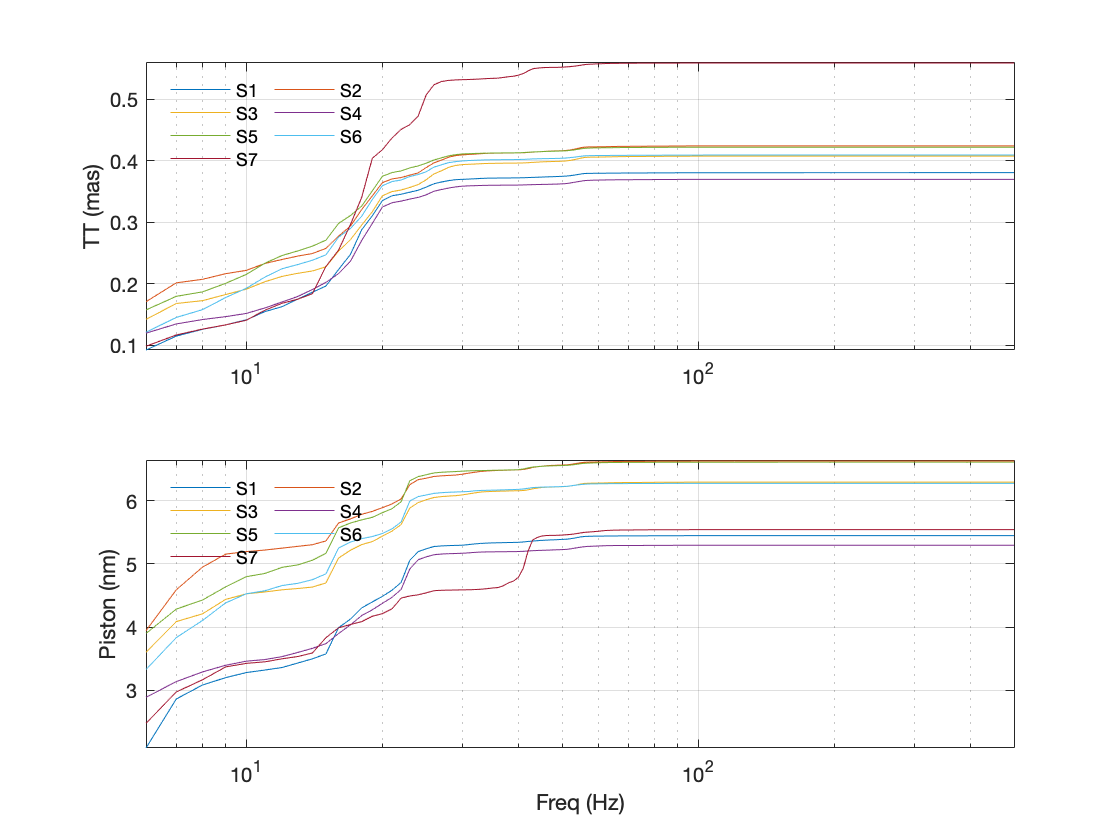

w = om(2:n_om);

figure(200);
set(gcf,'Name','Cumulative Contribution of each M1 segment');
for i1 = 1:7    
    subplot(211);
    tt_cumPSD_mas = rad2mas*sqrt( DeltaFs*( ...
        cumsum(sum(tt_psd(1:7,i1,2:end),1)) +...
        cumsum(sum(tt_psd(7:14,i1,2:end),1)) ));
    
    semilogx(w/2/pi, squeeze(tt_cumPSD_mas)); hold on;
    subplot(212);
    semilogx(w/2/pi, squeeze(1e9*sqrt(DeltaFs*cumsum( sum(piston_psd(:,i1,2:end),1) )))); hold on;
end

subplot(211);
ylabel('TT (mas)');
grid on; hold off; axis tight;
legend('S1','S2','S3','S4','S5','S6','S7','Orientation','Horizontal',...
    'Location','northwest','NumColumns',2); legend boxoff;
subplot(212)
ylabel('Piston (nm)');
xlabel('Freq (Hz)');
grid on; hold off; axis tight;
legend('S1','S2','S3','S4','S5','S6','S7','Orientation','Horizontal',...
    'Location','northwest','NumColumns',2); legend boxoff;

total_tt = rad2mas*sqrt( DeltaFs*sum(tt_psd(:,:,2:end), 'all') /7);
total_piston = 1e9*sqrt( DeltaFs*sum(piston_psd(:,:,2:end),'all') /7);
fprintf("Overall optical metrics:\n")

Overall optical metrics:


fprintf("TT=%.3gmas \t Piston=%.3gnm \n",total_tt, total_piston)

TT=0.417mas 	 Piston=6.04nm 


total_wfe = sqrt(((total_tt/rad2mas)^2 * R^2/4)*1e18 + total_piston^2);
fprintf("\n Total vibration induced WFE:%.3gnm\n", total_wfe)


 Total vibration induced WFE:10.4nm


## Rejection transfer functions (RTFs)

Function to compute the NS RTF (according to REQ-L3-OAD-35337)

function [rtf,L] = oad_NS_rtf(w)  

% PZT closed-loop bandwidth (Hz)
fz = 25;
% PZT control loop damping
delta = 0.6;
% TT loop sampling period
T = 5e-3;
% TT sensor delay
tau = 6e-3;
% TT "integral gain" - actually the considered integral gain is gi/T
gi = 0.3;

% Complex frequency vector
s = sqrt(-1)*w;

omz = fz*2*pi;
L = exp(-tau*s) .* (1-exp(-T*s))./(T*s) .* (gi/T./s) .*...
    (omz^2)./((omz^2)+2*omz*delta*s+(s.^2));

rtf = 1./(1 + L);

end

Function to compute the GLAO RTF (according to REQ-L3-OAD-35398)

function [rtf,L] = oad_AOTT_rtf(w)

% LTAO RTF (according to REQ-L3-OAD-35398)
fz = 800;       % ASM closed-loop bandwidth (Hz)
delta = 0.75;   % ASM control loop damping
T = 2e-3;   % TT loop sampling period
tau = 1e-3; % TT sensor delay
gi = 0.4;   % TT "integral gain"

% Complex frequency vector
s = sqrt(-1)*w;

omz = fz*2*pi;
L = exp(-tau*s) .* (1-exp(-T*s))./(T*s) .* (gi/T./s) .*...
    (omz^2)./((omz^2)+2*omz*delta*s+(s.^2));

rtf = 1./(1 + L);

end

Function to compute the differential piston RTF

function RTF_DP = getRTF_DP(om)
    
s = sqrt(-1)*om;

%% FROM DRD rev F
omz = 800*2*pi;
dz = .75;
Tp = 30;
taup= 6/1000;
gpi = .5;
Te = 2/1000;
taue = .1/1000;
geff = .8;

num = 1 + omz^2*geff*exp(-taue*s).*(exp(-Te*s)-1)./(Te*s.*    (omz^2+2*omz*dz*s+s.^2) );
den = 1 - omz^2*gpi*exp(-taup*s).*(exp(-Tp*s)-1)./(Tp^2*s.^2.*(omz^2+2*omz*dz*s+s.^2) );
RTF_DP = num./den;
    
end